# Linear Model Predictive Control

Evaluation of the MPC given an input reference

**Note:** N represents the length of the prediction horizon.


$$$$ \dot{x} = A x + B u + C$$$$



$$x_i = \left[ \matrix{
y \cr 
v_y \cr 
\phi \cr 
r \cr 
} \right]_{4 \times 1} , \quad i \in [0, N]$$



$$u_i = \left[ \matrix{
\delta_{command}, 
M_{TV}
} \right]_{1 \times 2} , \quad i \in [0, N]$$


% Parameters of the MPC
clear all
compare = false;
n_horizon = 60;
n_states = 6;
n_inputs = 2;
cd("/home/andreu/ros_ws/src/as/control/fuzzy_mpc/mtlb"); addpath(genpath('/home/andreu/ros_ws/src/as/control/fuzzy_mpc'))

### Reference vector

Reference states and (vx, psi) predicted from planner and previous step


$$x_0 = \left[ \matrix{
y_{0} \cr 
v_{y_{0}} \cr 
\phi_0 \cr 
r_0 \cr 
\delta \cr
\dot{\delta}
} \right]_{4 \times 1} $$
     
$$x_{ref} = \left[ \matrix{
x_{{ref}_1} \cr 
x_{{ref}_2}  \cr 
\vdots \cr 
x_{{ref}_N} 
} \right]_{4N \times 1}$$
  
$$u_i = \left[ \matrix{
\delta_{cmd} \quad
M_{TV}
} \right]_{1 \times 2} , \quad i \in [0, N]$$


x_0 = [0 0 0 0 0 0]';
u_prev_iter = [0, 0];
%x_0 = [meas_local.y(1) meas_local.vy(1) meas_local.psi(1) meas_local.r(1)]'; % Using data
%csv_file = readmatrix("debug/x0.csv"); x_0 = csv_file(end,1:4)';

% Reference states
x_ref_single = [1 0 0 0 0 0]';
x_ref = zeros(n_states*n_horizon, 1);
for i = 1:n_horizon
    % x_ref_single = [meas_local.y(i) meas_local.vy(i) meas_local.psi(i) meas_local.r(i)]'; % Using data
    x_ref((i-1)*n_states+1:i*n_states) = x_ref_single; 
end
% csv_file = readmatrix("debug/x_ref.csv"); x_ref = csv_file(end,:)';
% x_ref = reshape(x_ref, 6, []); x_ref = x_ref(1:4,:); x_ref = (x_ref(:).')';

% Predicted states from previous step
x_prev_single = [1 0 0 0 0 0]';
x_prev = zeros(n_states*n_horizon, 1);
for i = 1:n_horizon
    % x_prev_single = [meas_local.y(i) meas_local.vy(i) meas_local.psi(i) meas_local.r(i)]'; % Using data
    x_prev((i-1)*n_states+1:i*n_states) = x_prev_single; 
end
% csv_file = readmatrix("debug/x_prev.csv"); x_prev = csv_file(end,:)';
% x_prev = reshape(x_prev, 6, []); x_prev = x_prev(1:4,:); x_prev = (x_prev(:).')';

% Predicted controls from previous step
u_prev_single = [0; 0];
u_prev = zeros(n_horizon*n_inputs, 1);
for i = 1:n_horizon
    % u_prev_single = [in.st(i) in.mz(i)]; % Using data
    u_prev((i-1)*n_inputs+1:i*n_inputs) = u_prev_single; 
end
% csv_file = readmatrix("debug/u_prev.csv"); u_prev = zeros( n_inputs*n_horizon, 1);
% u_prev(1:2:end) = csv_file(end,:)';

vx = ones(n_horizon, 1) * 10;
% vx = meas.vx; % Using data
% csv_file = readmatrix("debug/vx.csv"); vx = csv_file(end,:)';


### Discrete model matrices for each step


$$$$  x_{k+1} = A_d x + B_d u + C_d$$$$


Ad = cell(n_horizon,1);
Bd = cell(n_horizon,1);
Cd = cell(n_horizon,1);
for i = 1:n_horizon
    from_x = i * n_states - n_states + 1;
    to_x = i * n_states;
    from_u = i * n_inputs - n_inputs + 1;
    to_u = i * n_inputs;
    %[Ad{i}, Bd{i}, Cd{i}] = direct_anfis_matrix(x_prev(from_x:to_x), u_prev(from_u:to_u), vx(i));
    [Ad{i}, Bd{i}, Cd{i}] = ltv_matrix(x_prev(from_x:to_x), x_ref(from_u:to_u), vx(i));
end

### Model condensing

Expressing the states as a function of the inputs and the initial state x_0.

                                                           
$$X = S  U + T x_0+W$$



$$X = \left[ \matrix{
x_1\cr
x_2\cr
\vdots\cr
x_N
}\right]_{4N\times1}$$
 
$$S = \left[ \matrix{
B_d & 0 & \cdots & 0 \cr
AB & B_d & \cdots & 0 \cr
\vdots & \vdots & \ddots & \vdots \cr
A_d^{N-1}B_d & A_d^{N-2}B_d & \cdots & B_d
} \right]_{4N \times 2N}$$
  
$$U = \left[ \matrix{
u_0 & u_1 & \cdots u_{N-1} 
} \right]_{2N \times 1}$$
   
$$T = \left[ \matrix{
A_d \cr 
A_d^2 \cr 
\vdots \cr 
A_d^N 
} \right]_{4N \times 4}$$
 
$$x_0 = \left[ \matrix{
y_{0} \cr 
v_{y_{0}} \cr 
\phi_0 \cr 
r_0 \cr 
} \right]_{4 \times 1} $$
   
$$W=\left[ \matrix{
C_1 \cr
A_2C_1+C_2 \cr
A_3A_2C_1+A_3C_2+C_3\cr
\vdots\cr
\sum_{i=1}^{k} \left( \prod_{j=i+1}^{k} A_j \right) C_i,

} \right]_{4N\times1}$$


% Fill matrix T
T = zeros(n_states * n_horizon, n_states);
for i = 1:n_horizon
    rows = (n_states * (i - 1) + 1):(n_states * i);
    Aprod = eye(n_states);
    for k = 1:i
        Aprod = Ad{k} * Aprod;
    end
    T(rows, 1:n_states) = Aprod;
end

% Fill matrix S
S = zeros(n_states * n_horizon, n_horizon * n_inputs);
for i = 1:n_horizon
    for j = 1:i
        Aprod = eye(n_states);
        for k = (j+1):i
            Aprod = Ad{k} * Aprod;
        end
        rows = (n_states * (i - 1) + 1):(n_states * i);
        cols = (n_inputs * (j - 1) + 1):(n_inputs * j);
        S(rows,cols) = Aprod * Bd{j};
    end
end

% Fill matrix W
W = zeros(n_states * n_horizon, 1);
for i = 1:n_horizon
    rows = (n_states*(i-1)+1):(n_states*i);
    wk = zeros(n_states, 1);

    for j = 1:i
        Aprod = eye(n_states);
        for k = j+1:i
            Aprod = Ad{k} * Aprod;
        end
        wk = wk + Aprod * Cd{j};
    end

    W(rows,1) = wk;
end

### Optimization function weights

Cost function for the MPC problem:


$$\[
\min_{u_{0:N-1},\, x_{0:N}}
\sum_{k=0}^{N-1}
\left(
\|x_k - x_k^{\mathrm{ref}}\|_Q^2 + \|R\,u_k\|^2
\right)
+
\|x_N - x_N^{\mathrm{ref}}\|_P^2
+
\Delta_{u_k}^T R_{\Delta} \Delta_{u_k}
\]
$$


The next step is to construct the Q and R matrices.


$$Q = \left[ \matrix{
q_y & 0 & 0 & 0 \cr
0 & q_{vy} & 0 & 0\cr
0 & 0 & q_{\phi} & 0 \cr
0 & 0 & 0 & q_r \cr
} \right]_{4 \times 4}$$

$$P = \left[ \matrix{
p_y & 0 & 0 & 0 &\cr
0 & p_{vy} & 0 & 0\cr
0 & 0 & p_{\phi} & 0 \cr
0 & 0 & 0 & p_r \cr
} \right]_{4 \times 4}$$
     
$$R = \left[ \matrix{
r_{\delta_{command}}  & 0\cr
 0 & r_{M_{TV}}
} \right]_{2 \times 2}$$

$$R_{\Delta} = \left[ \matrix{
r_{\delta_{command}}  & 0\cr
 0 & r_{M_{TV}}
} \right]_{2 \times 2}$$



$$\overline{Q} = \left[ \matrix{
Q & 0 & \cdots & 0 \cr
0 & Q & \cdots & 0 \cr
\vdots & \vdots & \ddots & \vdots \cr
0 & 0 & \cdots & P 
} \right]_{4N \times 4N}$$
       
$$\overline{R} = \left[ \matrix{
R & 0 & \cdots & 0 \cr
0 & R & \cdots & 0 \cr
\vdots & \vdots & \ddots & \vdots \cr
0 & 0 & \cdots & R 
} \right]_{2N \times 2N}$$
 
$$\overline{R_{\Delta}} = \left[ \matrix{
R_{\Delta} & 0 & \cdots & 0 \cr
0 & R_{\Delta} & \cdots & 0 \cr
\vdots & \vdots & \ddots & \vdots \cr
0 & 0 & \cdots & R_{\Delta} 
} \right]_{2N \times 2N}$$
 
$$D = \left[ \matrix{
I & 0 & 0 & \cdots & 0 \cr
-I & I & 0 & \cdots & 0 \cr
0 & -I & I & \cdots & 0\cr
\vdots & \vdots & \vdots & \ddots & \vdots \cr
0 & 0 & 0 & \cdots & I
} \right]_{2N \times 2N}$$
  
$$d = \left[ \matrix{
-u_{prev}\cr
0 \cr
0 \cr

\vdots \cr
} \right]_{2 \times 2}$$


To assign the weights, we use normalization around a scale factor


$$Q_{ii}=\frac{w_i}{x_{scale, i}^2}$$


% Scales for normalization
scale_y   = 0.1;   % m
scale_vy  = 0.1;   % m/s
scale_psi = 0.05;  % rad
scale_r   = 0.05;  % rad/s
scale_st  = 0.2;   % rad
scale_dst = 0.001; % rad/s
scale_mz  = 1000;  % Nm

% Initialize Q matrix
Q = diag([
    200/scale_y^2
    0/scale_vy^2
    0/scale_psi^2
    1/scale_r^2
    0/scale_st^2;
    0/scale_dst^2;
]);

% Initialize P matrix
P = diag([
    1000/scale_y^2
    0/scale_vy^2
    0/scale_psi^2
    0/scale_r^2
    0/scale_st^2;
    0/scale_dst^2;
]);

% Initialize R matrix
R = diag([
    1/scale_st^2
    0/scale_mz^2
]);

% Initialize Rd matrix
Rd = diag([
    2/scale_st^2
    0/scale_mz^2
]);

% Create Q_ matrix
Q_ = blkdiag(kron(eye(n_horizon-1), Q), P);

% Create R_ matrix
R_ = kron(eye(n_horizon), R);

% Create Rd_ matrix
Rd_ = kron(eye(n_horizon), Rd);

% Create D
D = zeros(n_horizon*n_inputs, n_horizon*n_inputs);
I = eye(n_inputs);
for k = 1:n_horizon
    % Diagonal block
    rows = (k-1)*n_inputs + (1:n_inputs);
    cols = (k-1)*n_inputs + (1:n_inputs);
    D(rows, cols) = I;

    % Subdiagonal block
    if k > 1
        cols_prev = (k-2)*n_inputs + (1:n_inputs);
        D(rows, cols_prev) = -I;
    end
end

% Create d
d = zeros(n_horizon*n_inputs, 1);
d(1:n_inputs) = -u_prev_iter;


### Model solution


$$H = 2(S^T\overline{Q}S + \overline{R})\;_{N \times N}$$



$$g=2S^TQ(Tx_0+W-X_{ref})$$



$$\Delta U^* = - H^{-1} g \;_{N \times 1}$$


% H matrix
H = 2 * (S' * Q_ * S + R_ + D' * Rd_ * D);
H = (H + H')/2; % Ensure symetry

% g vector
g = 2 * S' * Q_ * (T * x_0 + W - x_ref) + D' * Rd_ * d;

% ----------------- Simple solution ---------------------
% u_opt = -H \ g;


% -------------------- From Data  ----------------------
% u_opt = zeros(n_horizon*n_inputs,1);
% for i = 1:n_horizon
%     u_opt(n_inputs*(i-1)+1 : n_inputs*i) = [in.st(i); in.mz(i)];
% end

% -------------------- From MPC  ----------------------
% csv_file = readmatrix("debug/delta_u_opt.csv"); u_opt = zeros( n_inputs*n_horizon, 1);
% u_opt(1:2:end) = csv_file(end,:)';


% -------------- Optimization without restrictions ------------
% % Calculate the result
% [L, D, P] = ldl(H);
% 
% % Solve the system H * delta_u_opt = -g
% rhs = P * (-g);   % permuted right-hand side
% z   = L \ rhs;    % forward solve
% w   = D \ z;      % diagonal / block-diagonal solve
% ut  = L' \ w;     % backward solve
% u_opt = P' * ut;  % unpermute

% -------------- Optimization with restrictions ------------
% % Define bounds
% lb = zeros(n_horizon*n_inputs, 1);
% ub = zeros(n_horizon*n_inputs, 1);
% for i = 1:n_horizon
%     lb(n_inputs*(i-1)+1:n_inputs*i) = [-0.436; -0];
%     ub(n_inputs*(i-1)+1:n_inputs*i) = [0.436; 0];
% end
% 
% % Call quadprog
% options = optimoptions('quadprog', 'Display', 'off');
% 
% [u_opt, fval, exitflag] = quadprog(H, g, [], [], [], [], lb, ub, [], options);
% 
% % Check optimization status
% if exitflag ~= 1
%     warning('quadprog did not converge. Exitflag: %d', exitflag);
% end

% ---------------  Random check  ----------------
%u_opt = randn(n_inputs * n_horizon, 1);


### Prediction of the states

% Calculate the propagated states
pred_states = S * u_opt + T * x_0 + W;

% Recursive prediction
x = x_0;
X_recursive = zeros(n_states * n_horizon, 1);

for k = 1:n_horizon
    uk = u_opt((k-1)*n_inputs + (1:n_inputs));
    x = Ad{k} * x + Bd{k} * uk + Cd{k};
    X_recursive((k-1)*n_states + (1:n_states)) = x;
end

% Diference between condensed and recursive prediction
disp(norm(pred_states - X_recursive));

   1.6611e-15




% Cost of the solution
J_opt = (pred_states - x_ref)' * Q_ * (pred_states - x_ref) + u_opt' * R_ * u_opt

J_opt = 4.5463e+03

### Results

% Extract the first and fifth state from the predicted states
pred_state_y = [x_0(1); pred_states(1:n_states:end)];
pred_state_vy = [x_0(2); pred_states(2:n_states:end)];
pred_state_phi = [x_0(3); pred_states(3:n_states:end)];
pred_state_r = [x_0(4); pred_states(4:n_states:end)];

% Extract the first and fifth reference values from x_ref
ref_state_y = x_ref(1:n_states:end);
ref_state_vy = x_ref(2:n_states:end);
ref_state_phi = x_ref(3:n_states:end);
ref_state_r = x_ref(4:n_states:end);

% Extract control actions
delta_opt = u_opt(1:n_inputs:end);
mtv_opt   = u_opt(2:n_inputs:end);

% Predicted state for comparison
if compare
    csv_file = readmatrix("debug/pred_states.csv"); comp_pred_states = csv_file(end,:)';
    comp_pred_states = reshape(comp_pred_states, 6, []); comp_pred_states = comp_pred_states(1:4,:); comp_pred_states = (comp_pred_states(:).')';

    comp_pred_state_y = [x_0(1); comp_pred_states(1:n_states:end)];
    comp_pred_state_vy = [x_0(2); comp_pred_states(2:n_states:end)];
    comp_pred_state_phi = [x_0(3); comp_pred_states(3:n_states:end)];
    comp_pred_state_r = [x_0(4); comp_pred_states(4:n_states:end)];
end

% U opt for comparison
if compare
    csv_file = readmatrix("debug/delta_u_opt.csv"); comp_u_opt = zeros( n_inputs*n_horizon, 1);
    comp_u_opt(1:2:end) = csv_file(end,:)';

    comp_delta_opt = comp_u_opt(1:n_inputs:end);
    comp_mtv_opt = comp_u_opt(2:n_inputs:end);

end

ref_state_y = [x_0(1); ref_state_y];
ref_state_vy = [x_0(2); ref_state_vy];
ref_state_phi = [x_0(3); ref_state_phi];
ref_state_r = [x_0(4); ref_state_r];

% Time vector for the prediction horizon
time_horizon = 0:(n_horizon);

### Plot results

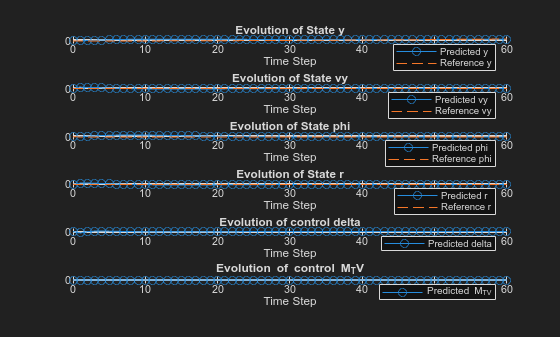

f = figure(1);
set(f, 'Visible', 'on');
% Plot for state y`
subplot(6, 1, 1);
plot(time_horizon, pred_state_y, '-o', 'DisplayName', 'Predicted y');
hold on;
plot(time_horizon, ref_state_y, '--', 'DisplayName', 'Reference y');
if compare plot(time_horizon, comp_pred_state_y, '-og', 'DisplayName', 'C++ MPC predicted y'); end
hold off;
xlabel('Time Step');
ylabel('y');
title('Evolution of State y');
legend;
grid on;

% Plot for state vy
subplot(6, 1, 2);
plot(time_horizon, pred_state_vy, '-o', 'DisplayName', 'Predicted vy');
hold on;
plot(time_horizon, ref_state_vy, '--', 'DisplayName', 'Reference vy');
if compare plot(time_horizon, comp_pred_state_vy, '-og', 'DisplayName', 'C++ MPC predicted vy'); end
hold off;
xlabel('Time Step');
ylabel('vy');
title('Evolution of State vy');
legend;
grid on;

% Plot for state phi
subplot(6, 1, 3);
plot(time_horizon, pred_state_phi, '-o', 'DisplayName', 'Predicted phi');
hold on;
plot(time_horizon, ref_state_phi, '--', 'DisplayName', 'Reference phi');
if compare plot(time_horizon, comp_pred_state_phi, '-og', 'DisplayName', 'C++ MPC predicted phi'); end
hold off;
xlabel('Time Step');
ylabel('phi');
title('Evolution of State phi');
legend;
grid on;

% Plot for state r
subplot(6, 1, 4);
plot(time_horizon, pred_state_r, '-o', 'DisplayName', 'Predicted r');
hold on;
plot(time_horizon, ref_state_r, '--', 'DisplayName', 'Reference r');
if compare plot(time_horizon, comp_pred_state_r, '-og', 'DisplayName', 'C++ MPC predicted r'); end
hold off;
xlabel('Time Step');
ylabel('r');
title('Evolution of State r');
legend;
grid on;

% Plot for input delta_opt
subplot(6, 1, 5);
plot(time_horizon, [0; delta_opt], '-o', 'DisplayName', 'Predicted delta');
hold on
if compare plot(time_horizon, [0; comp_delta_opt], '-og', 'DisplayName', 'C++ MPC predicted delta'); end
hold off
xlabel('Time Step');
ylabel('Delta opt');
title('Evolution of control delta');
legend;
grid on;

% Plot for input mtv_opt
subplot(6, 1, 6);
plot(time_horizon, [0; mtv_opt], '-o', 'DisplayName', 'Predicted M_{TV}');
hold on
if compare plot(time_horizon, [0; comp_mtv_opt], '-og', 'DisplayName', 'C++ MPC predicted M_{TV}'); end
hold off
xlabel('Time Step');
ylabel('M_{TV} opt');
title('Evolution of control M_TV');
legend;
grid on;